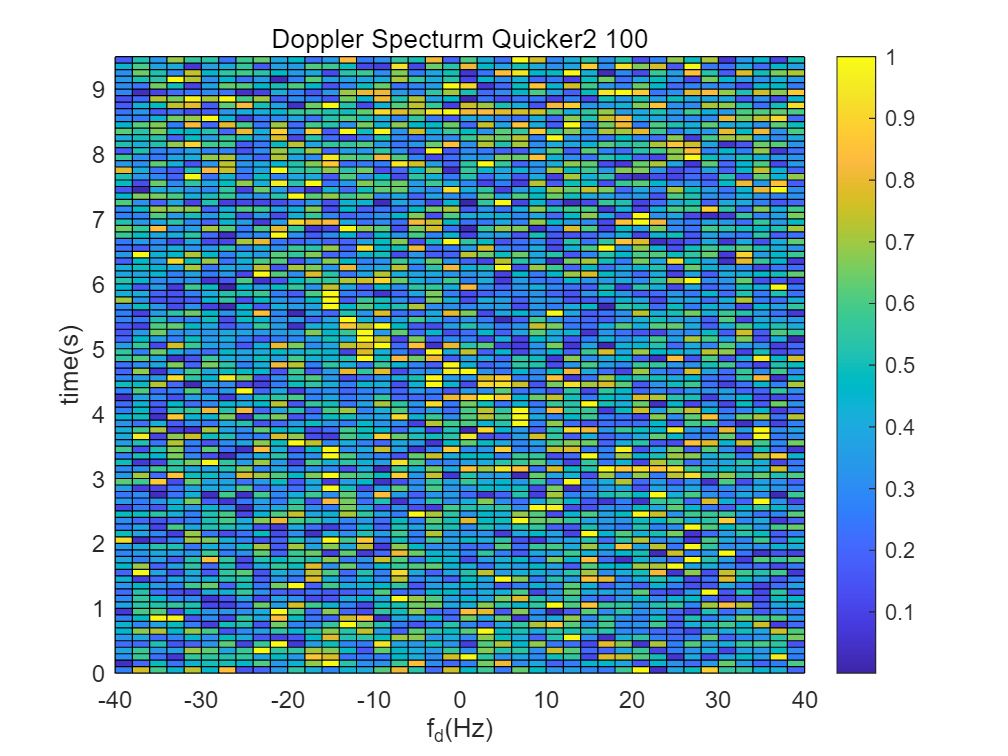

% 初始化参数
num_files = 96;
tau_values = 0:6;
fd_values = -40:2:40;
num_tau = length(tau_values);
num_fd = length(fd_values);
cors_size = [7, 41];  % 7x41大小
% 创建一个数组来存储最终结果
result = zeros(num_files, num_fd);

for k = 1:num_files
    % 加载文件
    filename = sprintf('cors/cors%d.mat', k);
    data = load(filename);
    cors = data.cors;
    
    % 找到每个文件中 cors 数组的最大值及其对应的行
    [max_value, max_index] = max(cors(:));
    [row, ~] = ind2sub(size(cors), max_index);
    
    % 归一化最大值所在行的数据
    normalized_row = cors(row, :) / max_value;
    result(k, :) = normalized_row;
end

% 绘制结果
range = 0:0.1:9.5;
freqd = -40:2:40;
[F,R]=meshgrid(freqd, range);
surf(F, R, result);
view(0,90);
ylim([0 9.5]);
xlim([-40 40]);
xlabel("f_{d}(Hz)");
ylabel("time(s)");
title("Doppler Specturm");
colorbar
saveas(gcf, 'Doppler_Spectrum.png');



% figure;
% imagesc(fd_values, (0:0.5:10), result);
% xlabel('Doppler Frequency (fd)');
% ylabel('Time (s)');
% title('Doppler Spectrum with Coherent Integration Time = 0.5 s');
% colorbar;
% axis xy;  
% saveas(gcf, 'Doppler_Spectrum.png');